## **HCP Main Sample - Whole-Brain Coupling Plot Across Conditions (176 frames)**

**Control Analysis**: All fMRI scan length: 176 frames. Computation of coupling measure-specific brain-average coupling values for all eight conditions, taking the mean across the four measure-specific brain-average coupling values per condition and creating the violin plot visualizing condition-specific differences in brain-average SC-FC coupling. Run ANOVA to test for significant differences between brain-average condition-specific SC-FC coupling.  

Before running this script: 

- run all scripts in HCP Data Prep 

**1. Compute brain-average coupling values **

1.1. Resting-state 

for i = 1:532
    whole_brain_values_HCP_rest{i,1} = mean(final_r_all_HCP_rest_176_frames_532{i,1}(:,1));% Pl
    whole_brain_values_HCP_rest{i,2} = mean(final_r_all_HCP_rest_176_frames_532{i,1}(:,2));% G 
    whole_brain_values_HCP_rest{i,3} = mean(final_r_all_HCP_rest_176_frames_532{i,1}(:,3));% Cos
    whole_brain_values_HCP_rest{i,4} = mean(final_r_all_HCP_rest_176_frames_532{i,1}(:,4));% SI 
   
end

Convert cell to table 

 whole_brain_values_HCP_rest_table = cell2table(whole_brain_values_HCP_rest);
 whole_brain_values_HCP_rest_table.Properties.VariableNames = {'Pl', 'G', 'Cos', 'SI'}

whole_brain_values_HCP_rest_table = 532×4 table
      Pl          G         Cos        SI   
    _______    _______    _______    _______

    0.22332    0.23031    0.24322    0.18233
    0.21993    0.23034    0.23641    0.12842
    0.24775    0.26465    0.28173    0.21677
    0.23065    0.23851    0.25676    0.20537
    0.26107    0.25199    0.27354    0.21125
    0.24386    0.25294    0.27182    0.23496
    0.25513    0.24653    0.26553    0.18815
     0.2116    0.23238    0.24021    0.18599
    0.22802    0.23707    0.25588    0.20824
    0.23288     0.2405    0.25345    0.17352
    0.26085    0.26219    0.28143    0.20737
    0.26607    0.27156    0.29965     0.2331
    0.24526    0.24908     0.2653    0.17307
    0.21723    0.23357    0.24714    0.16919
    0.25087    0.25943     0.2728    0.20945
    0.22897    0.23629    0.25612    0.19439


1.2. Emotion processing (176 frames)

for i = 1:532
    whole_brain_values_HCP_emotion{i,1} = mean(final_r_all_HCP_emotion_532{i,1}(:,1));% Pl
    whole_brain_values_HCP_emotion{i,2} = mean(final_r_all_HCP_emotion_532{i,1}(:,2));% G 
    whole_brain_values_HCP_emotion{i,3} = mean(final_r_all_HCP_emotion_532{i,1}(:,3));% Cos
    whole_brain_values_HCP_emotion{i,4} = mean(final_r_all_HCP_emotion_532{i,1}(:,4));% SI 
   
end

Convert cell to table 

 whole_brain_values_HCP_emotion_table = cell2table(whole_brain_values_HCP_emotion);
 whole_brain_values_HCP_emotion_table.Properties.VariableNames = {'Pl', 'G', 'Cos', 'SI'}

whole_brain_values_HCP_emotion_table = 532×4 table
      Pl          G         Cos         SI   
    _______    _______    _______    ________

    0.15874    0.18069    0.18416      0.1281
    0.17971    0.18118    0.19089     0.13498
    0.16282    0.16631    0.16981     0.13584
    0.11691    0.12941    0.12784    0.092762
    0.18926    0.17597    0.18696     0.15995
    0.15549    0.16715    0.17083      0.1412
    0.15393    0.15751    0.15502     0.11522
    0.20942     0.2074    0.22418     0.19199
    0.13149    0.13353    0.13596     0.10859
     0.1549    0.16317    0.16582     0.12122
     0.1729    0.18002    0.18078     0.14643
    0.18051    0.18957    0.19886     0.15811
    0.16788    0.18257    0.18569     0.12053
    0.13297    0.15542    0.14547    0.091491
    0.16904    0.17487    0.17824     0.12873
    0.18934     0.1876    0.20

1.3. Gambling (253 frames)

for i = 1:532
    whole_brain_values_HCP_gambling{i,1} = mean(final_r_all_HCP_gambling_176_frames_532{i,1}(:,1));% Pl
    whole_brain_values_HCP_gambling{i,2} = mean(final_r_all_HCP_gambling_176_frames_532{i,1}(:,2));% G 
    whole_brain_values_HCP_gambling{i,3} = mean(final_r_all_HCP_gambling_176_frames_532{i,1}(:,3));% Cos
    whole_brain_values_HCP_gambling{i,4} = mean(final_r_all_HCP_gambling_176_frames_532{i,1}(:,4));% SI 
   
end

Convert cell to table 

 whole_brain_values_HCP_gambling_table = cell2table(whole_brain_values_HCP_gambling);
 whole_brain_values_HCP_gambling_table.Properties.VariableNames = {'Pl', 'G', 'Cos', 'SI'}

whole_brain_values_HCP_gambling_table = 532×4 table
      Pl          G         Cos        SI   
    _______    _______    _______    _______

    0.18837    0.20739    0.20948    0.16128
    0.19605    0.19621    0.20251    0.12287
    0.21117    0.21462    0.22148    0.19217
    0.15148    0.16683    0.16298    0.11673
     0.2286    0.23149     0.2399    0.18943
    0.19963     0.2129    0.21652     0.1846
    0.20489    0.19981    0.20349    0.15844
    0.19432    0.20431    0.21089    0.16802
    0.18444    0.18433     0.1928    0.15108
    0.18286     0.1907    0.19101     0.1407
     0.2242    0.23067    0.23516      0.189
    0.23688    0.25071    0.26389    0.19138
    0.19753    0.21073    0.20883    0.14755
    0.20377    0.22447    0.22432    0.16341
    0.21398    0.22556    0.23182    0.17645
    0.21323    0.22834    0.23552    0.17614


1.4. Language (316 frames)

for i = 1:532
    whole_brain_values_HCP_language{i,1} = mean(final_r_all_HCP_language_176_frames_532{i,1}(:,1));% Pl
    whole_brain_values_HCP_language{i,2} = mean(final_r_all_HCP_language_176_frames_532{i,1}(:,2));% G 
    whole_brain_values_HCP_language{i,3} = mean(final_r_all_HCP_language_176_frames_532{i,1}(:,3));% Cos
    whole_brain_values_HCP_language{i,4} = mean(final_r_all_HCP_language_176_frames_532{i,1}(:,4));% SI 
   
end

Convert cell to table 

 whole_brain_values_HCP_language_table = cell2table(whole_brain_values_HCP_language);
 whole_brain_values_HCP_language_table.Properties.VariableNames = {'Pl', 'G', 'Cos', 'SI'}

whole_brain_values_HCP_language_table = 532×4 table
      Pl          G         Cos        SI   
    _______    _______    _______    _______

    0.21651    0.23584    0.24776    0.18027
    0.22833    0.23895    0.24817    0.15322
    0.23342    0.23903    0.24553    0.19835
    0.18897    0.20813    0.21427    0.14092
    0.20788    0.21301    0.22412    0.16545
    0.25092    0.25517    0.26616    0.21275
    0.20024    0.20409    0.20832    0.13552
    0.23351    0.23497    0.25012    0.18905
    0.26259    0.25119    0.27456    0.22904
    0.23921    0.23449    0.24847    0.19638
     0.2277    0.25167    0.25478    0.16519
    0.21767    0.23722    0.24848    0.17603
    0.21608    0.23838    0.24134    0.14007
    0.24429    0.26063    0.26621    0.18514
    0.20268    0.22571    0.22305    0.14508
    0.25822     0.2503    0.26993    0.22021


1.5. Motor (284 frames)

for i = 1:532
    whole_brain_values_HCP_motor{i,1} = mean(final_r_all_HCP_motor_176_frames_532{i,1}(:,1));% Pl
    whole_brain_values_HCP_motor{i,2} = mean(final_r_all_HCP_motor_176_frames_532{i,1}(:,2));% G 
    whole_brain_values_HCP_motor{i,3} = mean(final_r_all_HCP_motor_176_frames_532{i,1}(:,3));% Cos
    whole_brain_values_HCP_motor{i,4} = mean(final_r_all_HCP_motor_176_frames_532{i,1}(:,4));% SI 
   
end

Convert cell to table 

 whole_brain_values_HCP_motor_table = cell2table(whole_brain_values_HCP_motor);
 whole_brain_values_HCP_motor_table.Properties.VariableNames = {'Pl', 'G', 'Cos', 'SI'}

whole_brain_values_HCP_motor_table = 532×4 table
      Pl          G         Cos        SI   
    _______    _______    _______    _______

    0.20586    0.20829    0.22094    0.15788
    0.20052     0.2055    0.21004       0.13
    0.20449    0.20392    0.20797    0.17363
    0.16881    0.18029    0.18204    0.14315
    0.20094     0.1949    0.19533    0.15358
     0.2064    0.22022    0.22357    0.17539
    0.17835    0.17608    0.18584    0.14523
    0.18808    0.19645    0.20453    0.15973
    0.17941    0.18244    0.19026    0.14896
      0.175    0.18464     0.1886      0.135
    0.20631    0.21513    0.21802    0.15407
    0.23201    0.23056    0.24485    0.19232
    0.18657    0.19022    0.19158    0.12322
    0.20897    0.21637    0.22547     0.1713
    0.18763    0.19726    0.20115    0.14828
    0.21354    0.21897    0.22849    0.19039


1.6. Relational (232 frames)

for i = 1:532
    whole_brain_values_HCP_relational{i,1} = mean(final_r_all_HCP_relational_176_frames_532{i,1}(:,1));% Pl
    whole_brain_values_HCP_relational{i,2} = mean(final_r_all_HCP_relational_176_frames_532{i,1}(:,2));% G 
    whole_brain_values_HCP_relational{i,3} = mean(final_r_all_HCP_relational_176_frames_532{i,1}(:,3));% Cos
    whole_brain_values_HCP_relational{i,4} = mean(final_r_all_HCP_relational_176_frames_532{i,1}(:,4));% SI 
   
end

Convert cell to table 

 whole_brain_values_HCP_relational_table = cell2table(whole_brain_values_HCP_relational);
 whole_brain_values_HCP_relational_table.Properties.VariableNames = {'Pl', 'G', 'Cos', 'SI'}

whole_brain_values_HCP_relational_table = 532×4 table
      Pl          G         Cos        SI   
    _______    _______    _______    _______

    0.19987    0.22465     0.2267    0.15066
    0.20911    0.21913    0.22753    0.13765
    0.22484    0.22277    0.23462    0.20596
    0.17267    0.18413    0.18361     0.1425
    0.18301    0.18684    0.18889    0.15393
    0.20204    0.21741    0.22739    0.18255
    0.19414    0.19492    0.19803    0.15653
     0.2063    0.20862    0.22593    0.19954
    0.19567    0.19339    0.20112     0.1665
    0.22706    0.23546    0.24145    0.17514
      0.225    0.23392    0.23886    0.19128
    0.25188    0.24794    0.26885    0.21156
    0.18004    0.20566    0.20192    0.12231
    0.19159    0.20915    0.21026    0.15107
    0.23292    0.24015     0.2537    0.21045
    0.23702    0.24224    0.25352    0.18854

1.7. Social (274 frames)

for i = 1:532
    whole_brain_values_HCP_social{i,1} = mean(final_r_all_HCP_social_176_frames_532{i,1}(:,1));% Pl
    whole_brain_values_HCP_social{i,2} = mean(final_r_all_HCP_social_176_frames_532{i,1}(:,2));% G 
    whole_brain_values_HCP_social{i,3} = mean(final_r_all_HCP_social_176_frames_532{i,1}(:,3));% Cos
    whole_brain_values_HCP_social{i,4} = mean(final_r_all_HCP_social_176_frames_532{i,1}(:,4));% SI 
   
end

Convert cell to table 

 whole_brain_values_HCP_social_table = cell2table(whole_brain_values_HCP_social);
 whole_brain_values_HCP_social_table.Properties.VariableNames = {'Pl', 'G', 'Cos', 'SI'}

whole_brain_values_HCP_social_table = 532×4 table
      Pl          G         Cos        SI   
    _______    _______    _______    _______

    0.19885    0.23172    0.23543    0.16359
    0.21895    0.23572    0.24219    0.15429
    0.20433    0.22046    0.22401    0.17306
    0.17015    0.18822    0.18826    0.14547
    0.22843    0.23415    0.25079    0.20204
    0.20706    0.22536    0.22706    0.18906
    0.16269    0.18765    0.18455    0.10364
    0.22272     0.2286     0.2421    0.20138
    0.21127    0.22065    0.23182    0.17835
    0.18256    0.20431    0.20914    0.13019
     0.2193    0.23563    0.24388    0.18138
    0.22777    0.25033    0.26703    0.20476
    0.20612    0.23049    0.23533    0.15988
    0.18175    0.21643      0.204     0.1299
    0.20614    0.23138     0.2371    0.16668
    0.22021     0.2308    0.24167    0.19829


1.8. WM (405 frames)

for i = 1:532
    whole_brain_values_HCP_wm{i,1} = mean(final_r_all_HCP_wm_176_frames_532{i,1}(:,1));% Pl
    whole_brain_values_HCP_wm{i,2} = mean(final_r_all_HCP_wm_176_frames_532{i,1}(:,2));% G 
    whole_brain_values_HCP_wm{i,3} = mean(final_r_all_HCP_wm_176_frames_532{i,1}(:,3));% Cos
    whole_brain_values_HCP_wm{i,4} = mean(final_r_all_HCP_wm_176_frames_532{i,1}(:,4));% SI 
   
end

Convert cell to table 

 whole_brain_values_HCP_wm_table = cell2table(whole_brain_values_HCP_wm);
 whole_brain_values_HCP_wm_table.Properties.VariableNames = {'Pl', 'G', 'Cos', 'SI'}

whole_brain_values_HCP_wm_table = 532×4 table
      Pl          G         Cos        SI   
    _______    _______    _______    _______

    0.19634    0.22484    0.22321    0.14866
    0.19857    0.21066    0.21768    0.15986
    0.19582    0.21047    0.21109    0.16417
    0.16757    0.18108    0.17527    0.14591
    0.23359    0.23499    0.24485    0.20265
    0.20144    0.22277    0.22025    0.18346
    0.20662    0.20586    0.20635    0.15329
    0.21831    0.22348    0.23619    0.19733
    0.17307      0.182    0.18243    0.14092
    0.17773    0.19193    0.19119    0.14074
    0.21677    0.22594    0.23419    0.18109
    0.23562    0.24962    0.25931    0.20219
    0.19008    0.20771    0.20612    0.13516
     0.1927    0.21783    0.21115    0.14326
    0.23441    0.24058     0.2464    0.19778
    0.23273    0.23075    0.24669    0.19785


**2. Average coupling measures within the conditions **

2.1. Take average across all resting-state values 

Rest_values_from_all_measures = [whole_brain_values_HCP_rest_table.Pl whole_brain_values_HCP_rest_table.G whole_brain_values_HCP_rest_table.Cos whole_brain_values_HCP_rest_table.SI]

Rest_values_from_all_measures =     0.2233    0.2303    0.2432    0.1823
    0.2199    0.2303    0.2364    0.1284
    0.2478    0.2646    0.2817    0.2168
    0.2306    0.2385    0.2568    0.2054
    0.2611    0.2520    0.2735    0.2112
    0.2439    0.2529    0.2718    0.2350
    0.2551    0.2465    0.2655    0.1882
    0.2116    0.2324    0.2402    0.1860
    0.2280    0.2371    0.2559    0.2082
    0.2329    0.2405    0.2535    0.1735


Rest_all = mean(Rest_values_from_all_measures,2)

Rest_all =     0.2198
    0.2038
    0.2527
    0.2328
    0.2495
    0.2509
    0.2388
    0.2175
    0.2323
    0.2251


2.2. Take average across all emotion processing values 

Emotion_values_from_all_measures = [whole_brain_values_HCP_emotion_table.Pl whole_brain_values_HCP_emotion_table.G whole_brain_values_HCP_emotion_table.Cos whole_brain_values_HCP_emotion_table.SI]

Emotion_values_from_all_measures =     0.1587    0.1807    0.1842    0.1281
    0.1797    0.1812    0.1909    0.1350
    0.1628    0.1663    0.1698    0.1358
    0.1169    0.1294    0.1278    0.0928
    0.1893    0.1760    0.1870    0.1599
    0.1555    0.1671    0.1708    0.1412
    0.1539    0.1575    0.1550    0.1152
    0.2094    0.2074    0.2242    0.1920
    0.1315    0.1335    0.1360    0.1086
    0.1549    0.1632    0.1658    0.1212


Emotion_all = mean(Emotion_values_from_all_measures,2)

Emotion_all =     0.1629
    0.1717
    0.1587
    0.1167
    0.1780
    0.1587
    0.1454
    0.2082
    0.1274
    0.1513


2.3. Take average across all gambling values 

Gambling_values_from_all_measures = [whole_brain_values_HCP_gambling_table.Pl whole_brain_values_HCP_gambling_table.G whole_brain_values_HCP_gambling_table.Cos whole_brain_values_HCP_gambling_table.SI]

Gambling_values_from_all_measures =     0.1884    0.2074    0.2095    0.1613
    0.1960    0.1962    0.2025    0.1229
    0.2112    0.2146    0.2215    0.1922
    0.1515    0.1668    0.1630    0.1167
    0.2286    0.2315    0.2399    0.1894
    0.1996    0.2129    0.2165    0.1846
    0.2049    0.1998    0.2035    0.1584
    0.1943    0.2043    0.2109    0.1680
    0.1844    0.1843    0.1928    0.1511
    0.1829    0.1907    0.1910    0.1407


Gambling_all = mean(Gambling_values_from_all_measures,2)

Gambling_all =     0.1916
    0.1794
    0.2099
    0.1495
    0.2224
    0.2034
    0.1917
    0.1944
    0.1782
    0.1763


2.4. Take average across all language values 

Language_values_from_all_measures = [whole_brain_values_HCP_language_table.Pl whole_brain_values_HCP_language_table.G whole_brain_values_HCP_language_table.Cos whole_brain_values_HCP_language_table.SI]

Language_values_from_all_measures =     0.2165    0.2358    0.2478    0.1803
    0.2283    0.2389    0.2482    0.1532
    0.2334    0.2390    0.2455    0.1984
    0.1890    0.2081    0.2143    0.1409
    0.2079    0.2130    0.2241    0.1655
    0.2509    0.2552    0.2662    0.2128
    0.2002    0.2041    0.2083    0.1355
    0.2335    0.2350    0.2501    0.1890
    0.2626    0.2512    0.2746    0.2290
    0.2392    0.2345    0.2485    0.1964


Language_all = mean(Language_values_from_all_measures,2)

Language_all =     0.2201
    0.2172
    0.2291
    0.1881
    0.2026
    0.2463
    0.1870
    0.2269
    0.2543
    0.2296


2.5. Take average across all motor values 

Motor_values_from_all_measures = [whole_brain_values_HCP_motor_table.Pl whole_brain_values_HCP_motor_table.G whole_brain_values_HCP_motor_table.Cos whole_brain_values_HCP_motor_table.SI]

Motor_values_from_all_measures =     0.2059    0.2083    0.2209    0.1579
    0.2005    0.2055    0.2100    0.1300
    0.2045    0.2039    0.2080    0.1736
    0.1688    0.1803    0.1820    0.1431
    0.2009    0.1949    0.1953    0.1536
    0.2064    0.2202    0.2236    0.1754
    0.1784    0.1761    0.1858    0.1452
    0.1881    0.1964    0.2045    0.1597
    0.1794    0.1824    0.1903    0.1490
    0.1750    0.1846    0.1886    0.1350


Motor_all = mean(Motor_values_from_all_measures,2)

Motor_all =     0.1982
    0.1865
    0.1975
    0.1686
    0.1862
    0.2064
    0.1714
    0.1872
    0.1753
    0.1708


2.6. Take average across all relational values 

Relational_values_from_all_measures = [whole_brain_values_HCP_relational_table.Pl whole_brain_values_HCP_relational_table.G whole_brain_values_HCP_relational_table.Cos whole_brain_values_HCP_relational_table.SI]

Relational_values_from_all_measures =     0.1999    0.2246    0.2267    0.1507
    0.2091    0.2191    0.2275    0.1376
    0.2248    0.2228    0.2346    0.2060
    0.1727    0.1841    0.1836    0.1425
    0.1830    0.1868    0.1889    0.1539
    0.2020    0.2174    0.2274    0.1826
    0.1941    0.1949    0.1980    0.1565
    0.2063    0.2086    0.2259    0.1995
    0.1957    0.1934    0.2011    0.1665
    0.2271    0.2355    0.2414    0.1751


Relational_all = mean(Relational_values_from_all_measures,2)

Relational_all =     0.2005
    0.1984
    0.2220
    0.1707
    0.1782
    0.2073
    0.1859
    0.2101
    0.1892
    0.2198


2.7. Take average across all social values 

Social_values_from_all_measures = [whole_brain_values_HCP_social_table.Pl whole_brain_values_HCP_social_table.G whole_brain_values_HCP_social_table.Cos whole_brain_values_HCP_social_table.SI]

Social_values_from_all_measures =     0.1988    0.2317    0.2354    0.1636
    0.2190    0.2357    0.2422    0.1543
    0.2043    0.2205    0.2240    0.1731
    0.1702    0.1882    0.1883    0.1455
    0.2284    0.2341    0.2508    0.2020
    0.2071    0.2254    0.2271    0.1891
    0.1627    0.1877    0.1845    0.1036
    0.2227    0.2286    0.2421    0.2014
    0.2113    0.2207    0.2318    0.1784
    0.1826    0.2043    0.2091    0.1302


Social_all = mean(Social_values_from_all_measures,2)

Social_all =     0.2074
    0.2128
    0.2055
    0.1730
    0.2289
    0.2121
    0.1596
    0.2237
    0.2105
    0.1816


2.8. Take average across all working memory values 

Wm_values_from_all_measures = [whole_brain_values_HCP_wm_table.Pl whole_brain_values_HCP_wm_table.G whole_brain_values_HCP_wm_table.Cos whole_brain_values_HCP_wm_table.SI]

Wm_values_from_all_measures =     0.1963    0.2248    0.2232    0.1487
    0.1986    0.2107    0.2177    0.1599
    0.1958    0.2105    0.2111    0.1642
    0.1676    0.1811    0.1753    0.1459
    0.2336    0.2350    0.2449    0.2027
    0.2014    0.2228    0.2202    0.1835
    0.2066    0.2059    0.2064    0.1533
    0.2183    0.2235    0.2362    0.1973
    0.1731    0.1820    0.1824    0.1409
    0.1777    0.1919    0.1912    0.1407


Wm_all = mean(Wm_values_from_all_measures,2)

Wm_all =     0.1983
    0.1967
    0.1954
    0.1675
    0.2290
    0.2070
    0.1930
    0.2188
    0.1696
    0.1754


**3. Create the violin plot**  

3.1. Put all values into one table 

Mean_values_conditions = [Rest_all Emotion_all Gambling_all Language_all Motor_all Relational_all Social_all Wm_all]

Mean_values_conditions =     0.2198    0.1629    0.1916    0.2201    0.1982    0.2005    0.2074    0.1983
    0.2038    0.1717    0.1794    0.2172    0.1865    0.1984    0.2128    0.1967
    0.2527    0.1587    0.2099    0.2291    0.1975    0.2220    0.2055    0.1954
    0.2328    0.1167    0.1495    0.1881    0.1686    0.1707    0.1730    0.1675
    0.2495    0.1780    0.2224    0.2026    0.1862    0.1782    0.2289    0.2290
    0.2509    0.1587    0.2034    0.2463    0.2064    0.2073    0.2121    0.2070
    0.2388    0.1454    0.1917    0.1870    0.1714    0.1859    0.1596    0.1930
    0.2175    0.2082    0.1944    0.2269    0.1872    0.2101    0.2237    0.2188
    0.2323    0.1274    0.1782    0.2543    0.1753    0.1892    0.2105    0.1696
    0.2251    0.1513    0.1763    0.2296    0.1708    0.2198    0.1816    0.1754


% Mean_values_conditions_cell = num2cell(Mean_values_conditions)
% Mean_values_conditions_table = cell2table(Mean_values_conditions_cell)
% Mean_values_conditions_table.Properties.VariableNames = {'Rest', 'Emotion', 'Gambling', 'Language', 'Motor', 'Relational', 'Social', 'Working Memory'}

3.2. Create violin plots

% violinplot(Mean_values_conditions)
% ylabel('Brain-average Coupling (r)')
% xlabel('Condition')
% set(gca,'FontSize',15)
% xlabel('condition')
% ylabel('Mean Coupling Value')
% % [c,m,h,gnames] = multcompare(stats)
% % table = array2table(m,"RowNames",gnames, ...
% %    "VariableNames",["Mean","Standard Error"])

**4. Run ANOVAs **

Mean_values_conditions

Mean_values_conditions =     0.2198    0.1629    0.1916    0.2201    0.1982    0.2005    0.2074    0.1983
    0.2038    0.1717    0.1794    0.2172    0.1865    0.1984    0.2128    0.1967
    0.2527    0.1587    0.2099    0.2291    0.1975    0.2220    0.2055    0.1954
    0.2328    0.1167    0.1495    0.1881    0.1686    0.1707    0.1730    0.1675
    0.2495    0.1780    0.2224    0.2026    0.1862    0.1782    0.2289    0.2290
    0.2509    0.1587    0.2034    0.2463    0.2064    0.2073    0.2121    0.2070
    0.2388    0.1454    0.1917    0.1870    0.1714    0.1859    0.1596    0.1930
    0.2175    0.2082    0.1944    0.2269    0.1872    0.2101    0.2237    0.2188
    0.2323    0.1274    0.1782    0.2543    0.1753    0.1892    0.2105    0.1696
    0.2251    0.1513    0.1763    0.2296    0.1708    0.2198    0.1816    0.1754


groupnames = {'rest','emotion','gambling','language','motor','relational','social', 'wm'}

groupnames = 1×8 cell array
    {'rest'}    {'emotion'}    {'gambling'}    {'language'}    {'motor'}    {'relational'}    {'social'}    {'wm'}


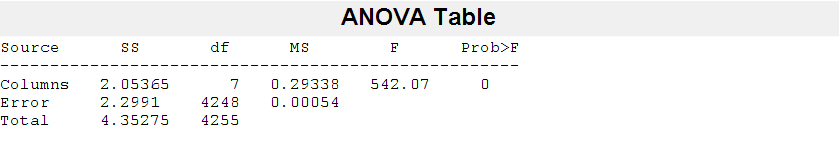

p = 0

tbl = 4×6 cell array
    {'Source' }    {'SS'    }    {'df'  }    {'MS'        }    {'F'       }    {'Prob>F'  }
    {'Columns'}    {[2.0536]}    {[   7]}    {[    0.2934]}    {[542.0687]}    {[       0]}
    {'Error'  }    {[2.2991]}    {[4248]}    {[5.4122e-04]}    {0×0 double}    {0×0 double}
    {'Total'  }    {[4.3527]}    {[4255]}    {0×0 double  }    {0×0 double}    {0×0 double}


stats = struct with fields:
    gnames: {8×1 cell}
         n: [532 532 532 532 532 532 532 532]
    source: 'anova1'
     means: [0.2450 0.1639 0.2024 0.2270 0.2044 0.2049 0.2181 0.2030]
        df: 4248
         s: 0.0233


[p,tbl,stats] = anova1(Mean_values_conditions,groupnames)

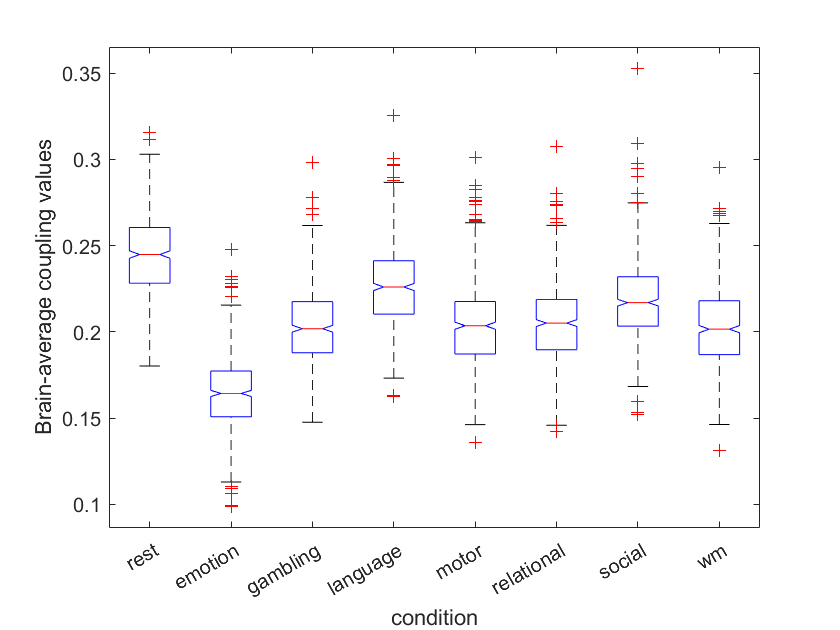

xlabel('condition')
ylabel('Brain-average coupling values')

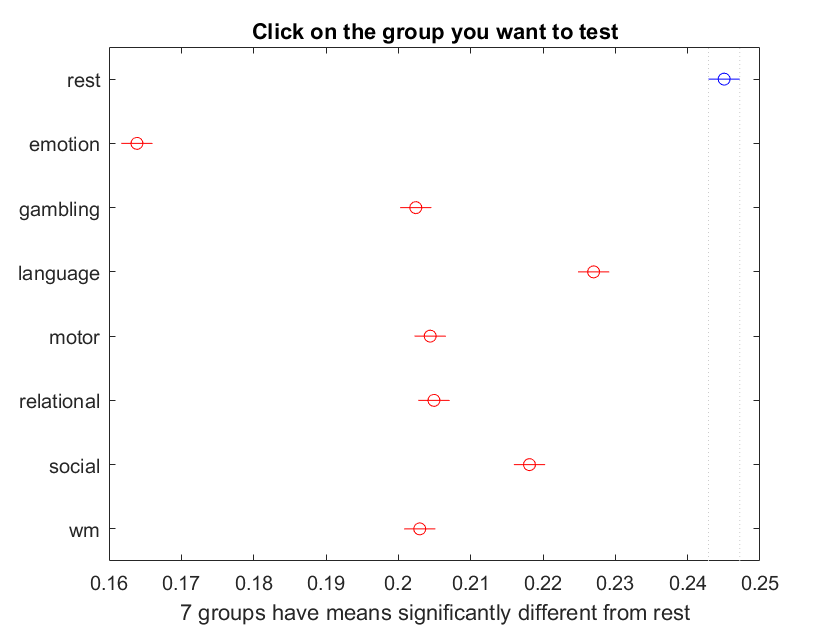

c =     1.0000    2.0000    0.0769    0.0812    0.0855         0
    1.0000    3.0000    0.0383    0.0426    0.0470         0
    1.0000    4.0000    0.0137    0.0180    0.0224         0
    1.0000    5.0000    0.0363    0.0406    0.0450         0
    1.0000    6.0000    0.0358    0.0401    0.0444         0
    1.0000    7.0000    0.0226    0.0269    0.0312         0
    1.0000    8.0000    0.0378    0.0421    0.0464         0
    2.0000    3.0000   -0.0429   -0.0386   -0.0342         0
    2.0000    4.0000   -0.0675   -0.0631   -0.0588         0
    2.0000    5.0000   -0.0449   -0.0405   -0.0362         0


gnames = 8×1 cell array
    {'rest'      }
    {'emotion'   }
    {'gambling'  }
    {'language'  }
    {'motor'     }
    {'relational'}
    {'social'    }
    {'wm'        }


[c,~,~,gnames] = multcompare(stats)

table = array2table(c,"VariableNames",["Group A", "Group B", "Lower Limit", "A-B", "Upper Limit", "P-value"])

table = 28×6 table
    Group A    Group B    Lower Limit       A-B        Upper Limit    P-value
    _______    _______    ___________    __________    ___________    _______

       1          2         0.076859       0.081183      0.085506           0
       1          3         0.038308       0.042631      0.046954           0
       1          4         0.013722       0.018045      0.022368           0
       1          5         0.036316       0.040639      0.044962           0
       1          6         0.035798       0.040122      0.044445           0
       1          7         0.022593       0.026917       0.03124           0
       1          8         0.037763       0.042086       0.04641           0
       2          3        -0.042875      -0.038552     -0.034229         

**5. Run Repeated-measures ANOVA **

data = Mean_values_conditions

data =     0.2198    0.1629    0.1916    0.2201    0.1982    0.2005    0.2074    0.1983
    0.2038    0.1717    0.1794    0.2172    0.1865    0.1984    0.2128    0.1967
    0.2527    0.1587    0.2099    0.2291    0.1975    0.2220    0.2055    0.1954
    0.2328    0.1167    0.1495    0.1881    0.1686    0.1707    0.1730    0.1675
    0.2495    0.1780    0.2224    0.2026    0.1862    0.1782    0.2289    0.2290
    0.2509    0.1587    0.2034    0.2463    0.2064    0.2073    0.2121    0.2070
    0.2388    0.1454    0.1917    0.1870    0.1714    0.1859    0.1596    0.1930
    0.2175    0.2082    0.1944    0.2269    0.1872    0.2101    0.2237    0.2188
    0.2323    0.1274    0.1782    0.2543    0.1753    0.1892    0.2105    0.1696
    0.2251    0.1513    0.1763    0.2296    0.1708    0.2198    0.1816    0.1754


subjects = (1:size(data,1))';  % Subject IDs

% Convert to table format
T = array2table(data, 'VariableNames', {'rest','emotion','gambling','language','motor','relational','social', 'wm'});
T.Subjects = subjects;

% Define Table
numbers = [1; 2; 3; 4; 5; 6; 7; 8]

numbers =      1
     2
     3
     4
     5
     6
     7
     8


Infotable = array2table(numbers, 'VariableNames', {'Condition'})

Infotable = 8×1 table
    Condition
    _________

        1    
        2    
        3    
        4    
        5    
        6    
        7    
        8    



% Define the repeated-measures model
rm = fitrm(T, 'rest-wm ~ 1', 'WithinDesign', Infotable);

% Perform repeated-measures ANOVA
ranovatbl = ranova(rm)

ranovatbl = 2×8 table
                             SumSq      DF       MeanSq        F       pValue    pValueGG    pValueHF     pValueLB  
                             ______    ____    __________    ______    ______    ________    ________    ___________

    (Intercept):Condition    2.0536       7       0.29338    985.27       0          0           0       4.4556e-123
    Error(Condition)         1.1068    3717    0.00029776                                                           



% Display results
disp(ranovatbl)

                             SumSq      DF       MeanSq        F       pValue    pValueGG    pValueHF     pValueLB  
                             ______    ____    __________    ______    ______    ________    ________    ___________

    (Intercept):Condition    2.0536       7       0.29338    985.27       0          0           0       4.4556e-123
    Error(Condition)         1.1068    3717    0.00029776                                                           



% Perform post-hoc tests
multcompare(rm, 'Condition')

ans = 56×7 table
    Condition_1    Condition_2    Difference      StdErr        pValue        Lower        Upper  
    ___________    ___________    __________    __________    __________    _________    _________

         1              2          0.081183      0.0011417    5.9881e-08     0.077722     0.084643
         1              3          0.042631      0.0011464    5.9881e-08     0.039156     0.046105
         1              4          0.018045      0.0012306    5.9881e-08     0.014315     0.021775
         1              5          0.040639      0.0011961    5.9881e-08     0.037014     0.044264
         1              6          0.040122      0.0011875    5.9881e-08     0.036522     0.043721
         1              7          0.026917      0.